syms alpha1(t) alpha2(t) Y

m1 = 0.5;
m2 = 0.15;
l1 = 0.1;
l2 = 0.1;
g = 9.8;

Da1 = diff(alpha1,t);
Da2 = diff(alpha2,t);
% REMEBER alpha is the angle with the vertical
x1 = l1*sin(alpha1);
y1 = -l1*cos(alpha1);
x2 = l1*sin(alpha1) + l2*sin(alpha2);
y2 = -l1*cos(alpha1) - l2*cos(alpha2);

T = 0.5*(m1*((diff(x1,t))^2 + (diff(y1,t))^2) + m2*((diff(x2,t))^2 + (diff(y2,t))^2));
V = m1*g*y1 + m2*g*y2;
L = T-V;

eqn1 = diff(diff(L,Da1),t) - diff(L,alpha1) == 0;
eqn2 = diff(diff(L,Da2),t) - diff(L,alpha2) == 0;
eqn1s = simplify(lhs(eqn1) - rhs(eqn1), 'Steps', 100)

$$eqn1s(t) = \frac{637\,\sin\left(\alpha_{1}\left(t\right)\right)}{1000}+\frac{3\,\sin\left(\alpha_{1}\left(t\right)-\alpha_{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\alpha_{2}\left(t\right)\right)}^{2}}{2000}+\frac{3\,\cos\left(\alpha_{1}\left(t\right)-\alpha_{2}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\alpha_{2}\left(t\right)}{2000}+\frac{13\,\frac{\partial^{2}}{\partial t^{2}}\alpha_{1}\left(t\right)}{2000}$$

eqn2s = simplify(lhs(eqn2) - rhs(eqn2), 'Steps', 100)

$$eqn2s(t) = \frac{147\,\sin\left(\alpha_{2}\left(t\right)\right)}{1000}-\frac{3\,\sin\left(\alpha_{1}\left(t\right)-\alpha_{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\alpha_{1}\left(t\right)\right)}^{2}}{2000}+\frac{3\,\cos\left(\alpha_{1}\left(t\right)-\alpha_{2}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\alpha_{1}\left(t\right)}{2000}+\frac{3\,\frac{\partial^{2}}{\partial t^{2}}\alpha_{2}\left(t\right)}{2000}$$


[VF,Subs] = odeToVectorField(eqn1s, eqn2s)

$$VF = \begin{array}{l} \left(\begin{array}{c} Y_{2}\\ \frac{3\,\cos\left(Y_{1}-Y_{3}\right)\,\sin\left(Y_{1}-Y_{3}\right)\,{Y_{2}}^{2}+13\,\sin\left(Y_{1}-Y_{3}\right)\,{Y_{4}}^{2}+1274\,\sin\left(Y_{1}\right)-1274\,\sin\left(Y_{3}\right)\,\cos\left(Y_{1}-Y_{3}\right)}{\sigma_{1}}\\ Y_{4}\\ -\frac{3\,\sin\left(Y_{1}-Y_{3}\right)\,{Y_{2}}^{2}+3\,\cos\left(Y_{1}-Y_{3}\right)\,\sin\left(Y_{1}-Y_{3}\right)\,{Y_{4}}^{2}-1274\,\sin\left(Y_{3}\right)+294\,\sin\left(Y_{1}\right)\,\cos\left(Y_{1}-Y_{3}\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=3\,{\cos\left(Y_{1}-Y_{3}\right)}^{2}-13 \end{array}$$

$$Subs = \left(\begin{array}{c} \alpha_{2}\\ {\mathrm{Dalpha}}_{2}\\ \alpha_{1}\\ {\mathrm{Dalpha}}_{1} \end{array}\right)$$

odefcn = matlabFunction(VF, 'Vars',{t,Y})

odefcn = function_handle with value:
    @(t,Y)[Y(2);(sin(Y(1)).*1.274e+3+sin(Y(1)-Y(3)).*Y(4).^2.*1.3e+1-sin(Y(3)).*cos(Y(1)-Y(3)).*1.274e+3+cos(Y(1)-Y(3)).*sin(Y(1)-Y(3)).*Y(2).^2.*3.0)./(cos(Y(1)-Y(3)).^2.*3.0-1.3e+1);Y(4);-(sin(Y(3)).*-1.274e+3+sin(Y(1)-Y(3)).*Y(2).^2.*3.0+sin(Y(1)).*cos(Y(1)-Y(3)).*2.94e+2+cos(Y(1)-Y(3)).*sin(Y(1)-Y(3)).*Y(4).^2.*3.0)./(cos(Y(1)-Y(3)).^2.*3.0-1.3e+1)]


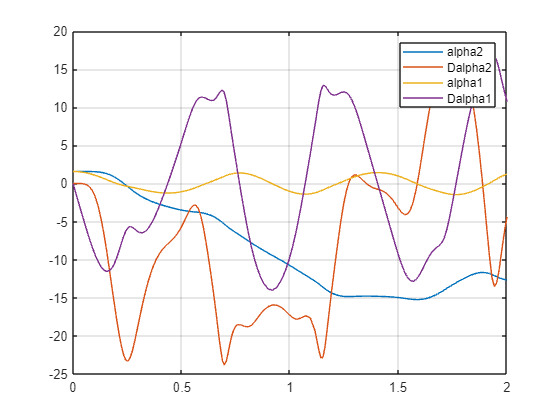

[X,Y] = ode45(odefcn, [0 2], [pi/2 0 pi/2 0]);

plot(X, Y)
grid
legend(string(Subs))

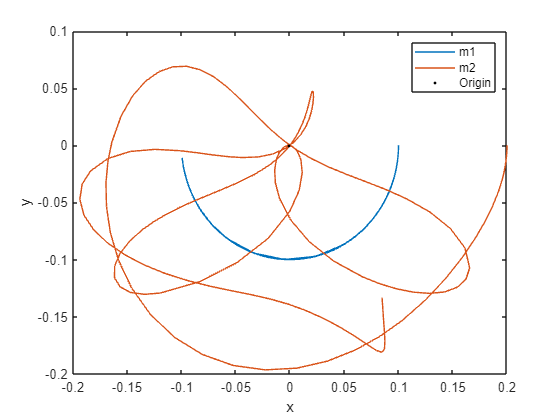


X1 = l1*sin(Y(:,3));
Y1 = -l1*cos(Y(:,3));
X2 = l1*sin(Y(:,3)) + l2*sin(Y(:,1));
Y2 = -l1*cos(Y(:,3)) - l2*cos(Y(:,1));
plot(X1,Y1,'DisplayName','m1')
hold on
plot(X2,Y2,'DisplayName','m2')
legend
xlabel('x')
ylabel('y')
plot(0,0,'.k','DisplayName','Origin')